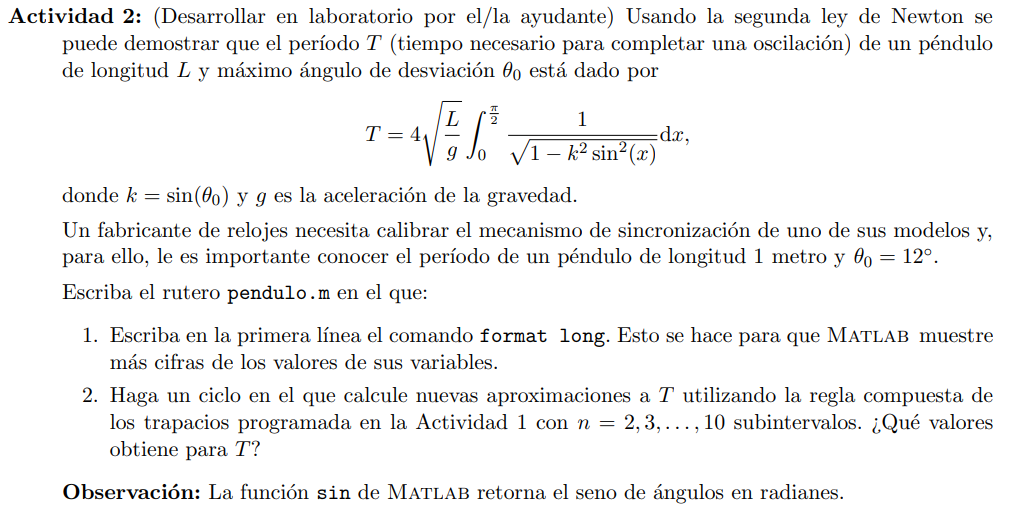

En esta actividad vamos a calcular la siguiente integral


$$T=4\sqrt{\frac{L}{g}}\int_0^{\frac{\pi}{2}} \frac{1}{\sqrt{1-k^2\sin^2(x)}}dx$$


con $k=\sin(\theta_0)$.

Vamos a considerar que $g=9.79$

format long
% datos
L=1; g=9.79; theta0=(12*pi)/180;
k=sin(theta0);


¿Cual es la funcion a integrar?


$$f(x)=\frac{1}{\sqrt{1-k^2\sin^2(x)}}$$


f = @(x) 1/sqrt(1-k^2*(sin(x)).^2);
n=2:10; ytrap=zeros(1,9); ysimp=zeros(1,9);

Vamos a calcular una aproximacion a la integral


$$I=\int_0^{\frac{\pi}{2}}\frac{1}{\sqrt{1-k^2\sin^2(x)}}dx$$


a estas aproximaciones las llamaremos $I_{aprox}$

%Calculo de la integral
for i=1:9
    ytrap(i)=trapecios(f,0,pi/2,n(i));
    ysimp(i)=simpson(f,0,pi/2,n(i));
end

Las soluciones aproximadas son:

 
$$T\approx 4\sqrt{\frac{L}{g}}I_{aprox}$$


%Calculo de la solucion
ytrap=4*sqrt(L/g)*ytrap; ysimp=4*sqrt(L/g)*ysimp;

Los datos los resumiremos en la siguiente tabla

%Tabla
T = table();
T.Iteracion = n';
T.Trapecios = ytrap';
T.Simpson = ysimp';
disp(T)

    Iteracion       Trapecios            Simpson     
    _________    ________________    ________________

        2        2.03054597183152    2.03029819381105
        3        2.03036013831617    2.03036011626801
        4        2.03036012178172     2.0303601217795
        5        2.03036012178005    2.03036012178005
        6        2.03036012178005    2.03036012178005
        7        2.03036012178005    2.03036012178005
        8        2.03036012178005    2.03036012178005
        9        2.03036012178005    2.03036012178005
       10        2.03036012178005    2.03036012178005



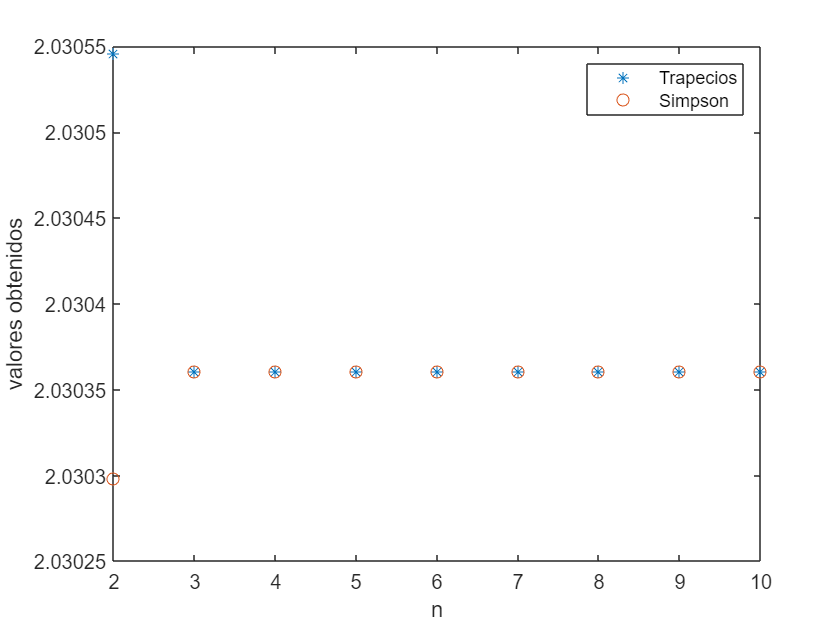

plot(n,ytrap,'*',n,ysimp,'o'); xlabel('n'); ylabel('valores obtenidos');
legend('Trapecios','Simpson')